clc,clear,close all

sps = 4;
M = 16;                 % Modulation order
k = log2(M);            % Bits per symbol
EbNoVec = (1:11);       % Eb/No values (dB)

codeRate = 2/3;                          % для кода со скоростью 2/3 с помощью функции poly2trellis. 

numSymPerFrame = 2^12%1000000;   % Number of QAM symbols per frame

numSymPerFrame = 4096




snr = convertSNR(EbNoVec,"ebno","snr",BitsPerSymbol=k, ...
    SamplesPerSymbol=sps, ...
    CodingRate=codeRate);

berEst = zeros(size(EbNoVec));
for n = 1:length(snr)
    % Reset the error and bit counters
    numErrs = 0;
    numBits = 0;
    
    while numErrs < 100 || numBits < 1e5
        % rng default  % генератор случайных чисел по умолчанию
        % Generate binary data and convert to symbols
        dataIn = randi([0 1],numSymPerFrame*k,1);
        % ПРИМЕНЕНИЕ СВЕРТОЧНОГО КОДА:

        constrlen = [5 4];          % Длина кодового ограничения
        genpoly = [23 35 0; 0 5 13]; % Создание Полиномов

        tPoly = poly2trellis(constrlen,genpoly); %Определите решетку сверточного кодирования 
        
                                                 % Определенная решетка представляет собой сверточный код, который функция convenc 
                                                 % использует для кодирования двоичного вектора dataIn.
        
        % КОДИРОВАНИЕ ВХОДНЫХ ДАННЫХ:

        dataEnc = convenc(dataIn,tPoly);
        dataSym = bit2int(dataEnc,k);
        
        % QAM модулирование 
        txSig = qammod(dataSym,M);

        % СОЗДАНИЕ ФИЛЬТРА ПРИПОДНЯТОГО КОСИНУСА:
        filtlen = 10; %Длина фильтра в символах
        rolloff = 0.25; %Коэффициент затухания фильтра
        rrcFilter = rcosdesign(rolloff,filtlen,sps); % функция для создания фильтра Прип.Кос.
        txSignal = upfirdn(txSig,rrcFilter,sps,1);

        % Pass through AWGN channel
        rxSig = awgn(txSignal,snr(n),'measured');
        rxFiltSignal = ...
            upfirdn(rxSig,rrcFilter,1,sps);       % Downsample and filter
        rxFiltSignal = ...
            rxFiltSignal(filtlen + 1:end - filtlen);
        
        % Demodulate the noisy signal
        rxSym = qamdemod(rxFiltSignal,M);
        % Convert received symbols to bits
        codedDataOut = int2bit(rxSym,k);
        traceBack = 16;                     
        numCodeWords = ...
            floor(length(codedDataOut)*2/3); % Количество полных кодовых слов
        dataOut = ...
            vitdec(codedDataOut(1:numCodeWords*3/2), ...
            tPoly,traceBack,'cont','hard');  % Декодирование данных
        
        % Calculate the number of bit errors
        decDelay = 2*traceBack; %Задержка декодера [бит]
        nErrors = biterr(dataIn(1:end - decDelay),dataOut(decDelay + 1:end));
        
        % Increment the error and bit counters
        numErrs = numErrs + nErrors;
        numBits = numBits + numSymPerFrame*k;
    end
    
    % Estimate the BER
    berEst(n) = numErrs/numBits
end

berEst =     0.4917         0         0         0         0         0         0         0         0         0         0


berEst =     0.4917    0.4734         0         0         0         0         0         0         0         0         0


berEst =     0.4917    0.4734    0.4416         0         0         0         0         0         0         0         0


berEst =     0.4917    0.4734    0.4416    0.3605         0         0         0         0         0         0         0


berEst =     0.4917    0.4734    0.4416    0.3605    0.2433         0         0         0         0         0         0


berEst =     0.4917    0.4734    0.4416    0.3605    0.2433    0.1114         0         0         0         0         0


berEst =     0.4917    0.4734    0.4416    0.3605    0.2433    0.1114    0.0321         0         0         0         0


berEst =     0.4917    0.4734    0.4416    0.3605    0.2433    0.1114    0.0321    0.0050         0         0         0


berEst =     0.4917    0.4734    0.4416    0.3605    0.2433    0.1114    0.0321    0.0050    0.0007         0         0


berEst =     0.4917    0.4734    0.4416    0.3605    0.2433    0.1114    0.0321    0.0050    0.0007    0.0001         0


berEst =     0.4917    0.4734    0.4416    0.3605    0.2433    0.1114    0.0321    0.0050    0.0007    0.0001    0.0000


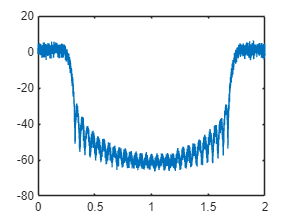

% window = 2;
[pxx,wx] = pwelch(txSignal);
plot(wx/pi,10*log10(pxx))

berTheoryawgn = berawgn(EbNoVec,'qam',M);
semilogy(EbNoVec,berEst,'*')
hold on
semilogy(EbNoVec,berTheoryawgn)
hold on
% spect = distspec(tPoly,1)
spect = distspec(tPoly,8);
berTheoryCoded = bercoding(EbNoVec,'conv','hard',codeRate,spect,'qam',M,'nondiff')

berTheoryCoded =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.1524    0.0159    0.0012    0.0001    0.0000


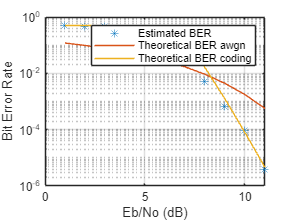

semilogy(EbNoVec,berTheoryCoded)
grid
legend('Estimated BER','Theoretical BER awgn','Theoretical BER coding')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')